The Build-Up of Aerosols Carrying the SARS-CoV-2 Coronavirus paper


$$\frac{d}{d t} C=E / V_{I}-\lambda C$$


$\lambda$ the decay coefficient of the concentration

$E$ the exhalation rate

$V_I$the volume of the pyramid

Experimental investigation of indoor aerosol dispersion and accumulation in the context of COVID-19 Paper,

Room volumne is (not $V_I$):


$$V = 7.8 \times 5.7 \times 2.7 \mathrm{~m} \approx 120 m^3$$


The differential equation is


$$\frac{d c}{d t}=R-\lambda c$$


$R$ particle injection rate

The solution to above is 


$$c^{*}(t)=\frac{R^{*}}{\lambda^{*}}\left(1-e^{-\lambda^{*} t}\right)$$


The simulated result is (not mask)


$$\begin{array}{ccc}
R^{*}(\% \mathrm{~h}) & \lambda^{*}\left(\mathrm{~h}^{-1}\right) & c_{\mathrm{sat}}^{*}=R^{*} / \lambda^{*}(\%) \\
\hline 0.53 \pm 0.11 & 0.46 \pm 0.11 & 1.13 \pm 0.057
\end{array}$$


The simulated result with controlled ACH:


$$\begin{array}{lccc}
\mathrm{ACH} & R^{*}(\% / \mathrm{h}) & \lambda^{*}\left(\mathrm{~h}^{-1}\right) & c_{\text {sat }}^{*}=R^{*} / \lambda^{*}(\%) \\
\hline 0 & 0.53 & 0.46 & 1.13 \\
1.7 & 0.48 & 1.36 & 0.35 \\
2.45 & 0.52 & 2.19 & 0.24 \\
3.2 & 0.41 & 2.27 & 0.18
\end{array}$$


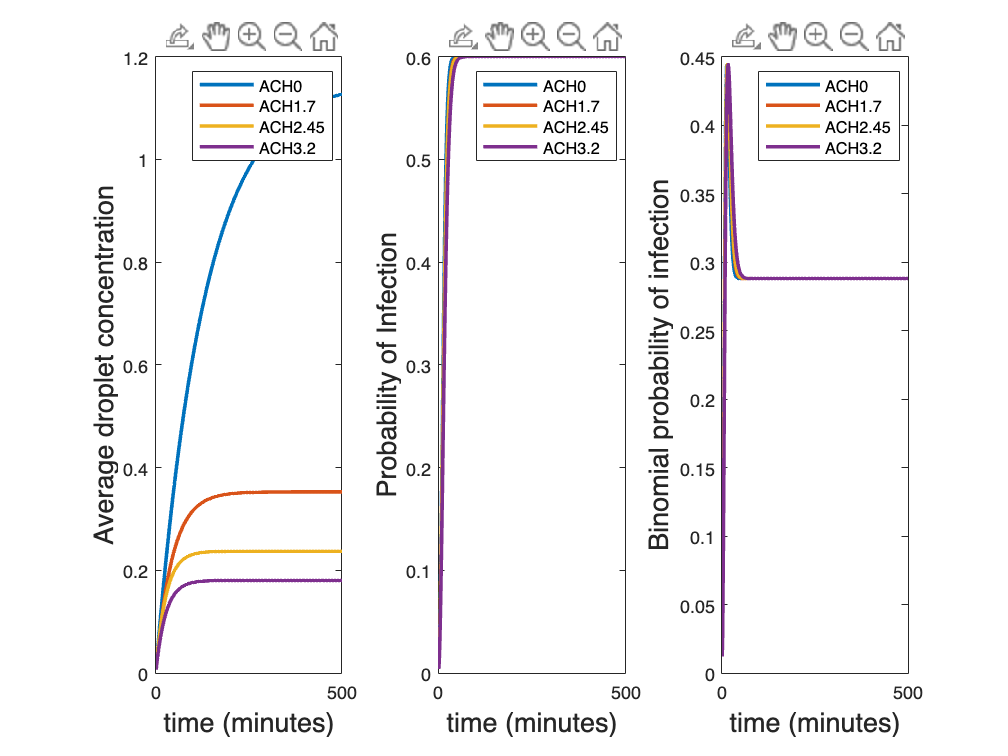

R = [0.53/60,0.48/60,0.52/60,0.41/60];
lambda = [0.46/60,1.36/60,2.19/60,2.27/60];
%C(1)=C(1)/k
for i = 1:4
    C(1) = R(i);
    k = lambda(i);
    p(1)=0.6*(1-exp(-C(1))); %We are assuming that most people are
    pb(1)=(factorial(3)/(factorial(2)*factorial(1)))*p(1)^1*(1-p(1))^2;
    for j=2:1:500
    C(j)=(C(1)/k)*(1-exp(-k*j));
    p(j)=0.6*(1-exp(C(j)/k-(C(1)/k)*j));
    pb(j)=(factorial(3)/(factorial(2)*factorial(1)))*p(j)^1*(1-p(j))^2;
    end
subplot(1,3,1)
plot(C,'LineWidth',2);hold on
ylabel('Average droplet concentration','FontSize',15), xlabel('time (minutes)','FontSize',15)
subplot(1,3,2)
plot(p,'LineWidth',2);hold on
ylabel('Probability of Infection','FontSize',15), xlabel('time (minutes)','FontSize',15)
subplot(1,3,3)
plot(pb,'LineWidth',2);hold on
ylabel('Binomial probability of infection','FontSize',15), xlabel('time (minutes)','FontSize',15)
end
subplot(1,3,1)
legend('ACH0','ACH1.7','ACH2.45','ACH3.2')
subplot(1,3,2)
legend('ACH0','ACH1.7','ACH2.45','ACH3.2')
subplot(1,3,3)
legend('ACH0','ACH1.7','ACH2.45','ACH3.2')


%


$$\lambda=k_{v}+k_{s}+k_{d}$$


Bus Station:


$$V_{bus} = 77.72 m^3$$



$$(E/V_I)_{bus} = \frac{2.45}{3}$$



$$\lambda_{bus} = 0.05$$


Chinese Restaurant:


$$k_v  = 0 $$



$$k_s = 0$$



$$k_d =0.0031$$



$$\lambda_{res}=k_{v}+k_{s}+k_{d} = 0.0031$$



$$(E/V_I)_{res} = 0.0086$$


Korean Call Center: